# Moving Average

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

rng(123)
x = 0:0.1:8

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y = sin(x) + 0.1*randn(size(x))

y =     0.0764    0.0393    0.0952    0.3157    0.4562    0.4471    0.6981    0.7064    0.7141    0.7538    0.7860    0.9476    0.9187    0.7960    0.9506    1.0821    0.9085    0.9454    0.9861    0.9553    0.9413    0.9696    0.8986    0.7744    0.7375    0.5339    0.4790    0.3690    0.1980    0.2936   -0.0297    0.0351   -0.0714   -0.1589   -0.2657   -0.4431   -0.4725   -0.3801   -0.4731   -0.6872   -0.7157   -0.9103   -0.9277   -0.9482   -0.7619   -1.0166   -0.9989   -0.8964   -0.9906   -0.9365


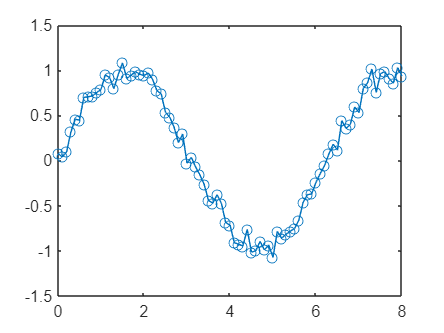

plot(x,y,"o-")

## Task 1

You can interactively program how you want to smooth data with the **Smooth Data** task. A **Smooth Data** task has been added to the script `movingaverage.mlx`. In this practice, you will use use the task to smooth a sine curve using a moving average.

**TASK1**

Create a vector named `ySm` that contains the centered 3-point moving average of `y`. To do this, you need to set:

- **Input data** to `y`

- **X-axis** to `x`

- **Smoothing method** to `Moving` `mean` with a `Moving` `window` that is `Centered` and `3` elements long

Display the results by leaving both `Smoothed` `Data` and `Input` `data` selected.

**Hint1**

The **Input data**, **X-axis**, and **Smoothing method** fields are labeled. Underneath **Smoothing method** change `Smoothing` `Factor` to `Moving` `window` and ensure `Centered` is selected. The numeric value should be `3`. You can set the output variable name at the top of the task.

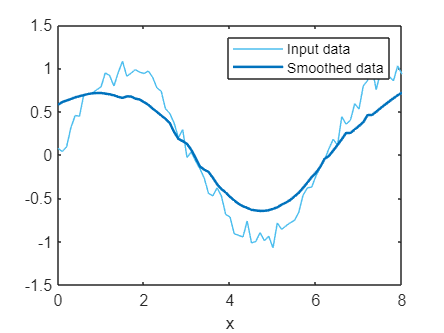

% Smooth input data
ySm = smoothdata(y,"movmean",3,"SamplePoints",x);

% Display results
clf
plot(x,y,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(x,ySm,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("x")

## Task 2

Click the triangle to view the code that creates and plots the smooth data.

The `smoothdata` function in the first line of code creates the smoothed data. You need to specify the data, method (here, `"movmean"` with an *n*-element window). You can also specify the *x*-data using the `"SamplePoints"` name value pair.

**TASK2**

Use the `smoothdata` function to create a vector named `ySm17` that contains the centered 17-point moving average of `y`.

**Hint2**

Use the generated code from the live task to see how to use the `smoothdata` function.

`dataSm` `=` `smoothdata``(``yData``,``"movmean"``,``num``,``"SamplePoints"``,``xData``)`

ySm17 = smoothdata(y,"movmean",17,"SamplePoints",x)

ySm17 =     0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496    0.1496


## Task 3

**TASK3**

Plot `ySm17` as a function of `x` with point markers and a solid line. Add the plot to the same figure using `hold` `on` and `hold` `off`.

**Hint3**

Use the `".-"` line specification with the `plot` function.

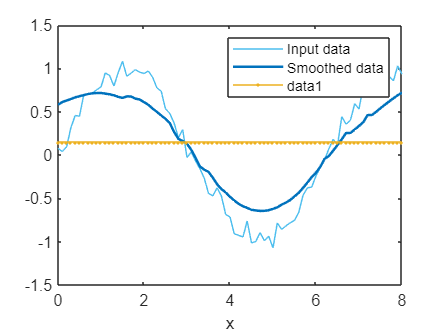

hold on
plot(x,ySm17,".-")
hold off